# SPEECH

Speech signals fall into three processing categories: **recognition** (identifying words or speakers), **synthesis** (converting text to speech), and **coding** (compressing speech to save bandwidth).

## Time-Domain Speech Processing

### Speech Production

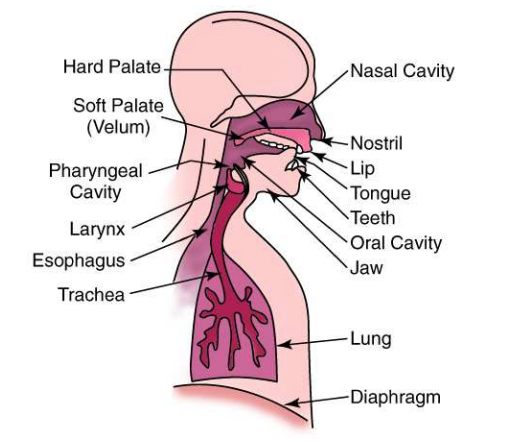

The human vocal system creates two types of sounds:

**Voiced sounds** (e.g., vowels) are made by air vibrating the vocal cords, producing quasi-periodic waveforms. The pitch period — roughly 8 ms for men and 4 ms for women — gives voiced speech its periodic character.

**Unvoiced sounds** (e.g., "s", "f") are generated by air turbulence through constrictions in the vocal tract. They are noise-like, lower in amplitude, and faster-oscillating than voiced sounds.

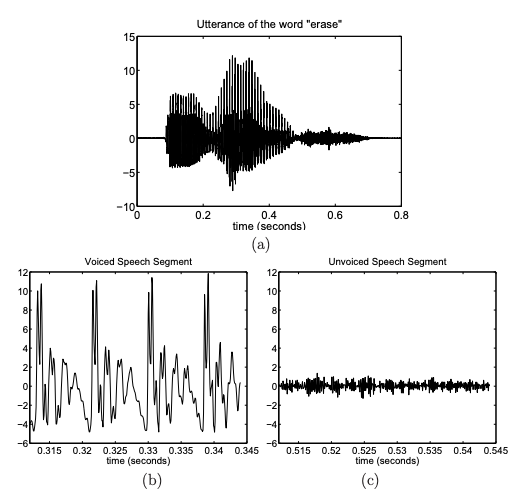

## Classification of Voiced/Unvoiced Speech

Distinguishing between these two sound types is a key step in most speech processing algorithms, typically done using short time-frame analysis.

Read in the speech signal 'Start.wav'; plot the signal; and listen to the signal.

### **Part 1:**

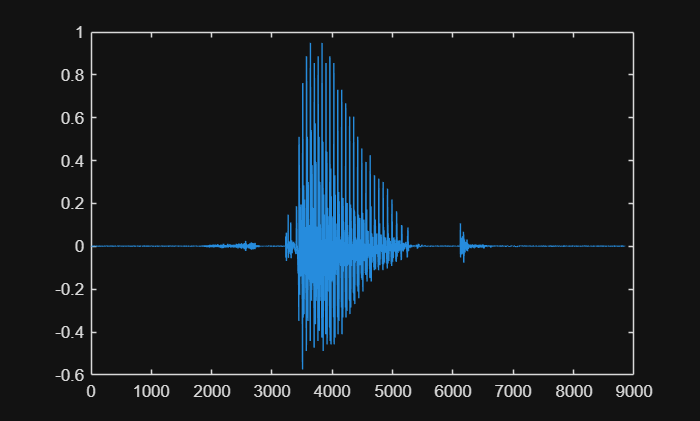

[speechSig, fs] = audioread('Start.wav') ;
figure
plot(speechSig)

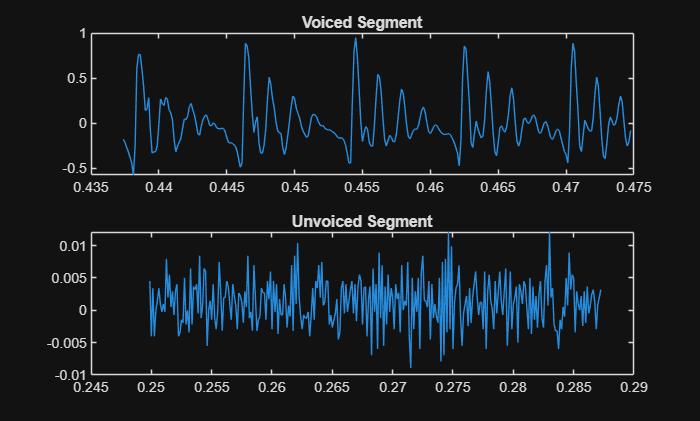

% Play Start.wav
playObj = audioplayer(speechSig,fs) ;
playblocking(playObj) ;

tAxis = (0:length(speechSig)-1)/fs ; % time = speech signal length / sampling frequency

% Choose a start sample index for both the voiced segment and unvoiced segment:
indexVoicedStart   = 3500;   % near start of voiced section (just after unvoiced)
indexUnVoicedStart = 2000;   % before sample 3000 — unvoiced region near start

% Store the VOICED segment (300 long, starting from indexVoicedStart):
voiceSig      = speechSig(indexVoicedStart : indexVoicedStart + 299);
tAxisVoiceSig = tAxis(indexVoicedStart : indexVoicedStart + 299);

% Store the UNVOICED segment (300 long, starting from indexUnVoicedStart):
unVoiceSig      = speechSig(indexUnVoicedStart : indexUnVoicedStart + 299);
tAxisUnVoiceSig = tAxis(indexUnVoicedStart : indexUnVoicedStart + 299);

figure

subplot(2,1,1)
plot(tAxisVoiceSig, voiceSig) ;
title("Voiced Segment")

subplot(2,1,2)
plot(tAxisUnVoiceSig, unVoiceSig) ;
title("Unvoiced Segment")

### Part 2:

Here, our goal is to use the findpeaks() setting to accurately find the highest spike points in the voiceSig signal.

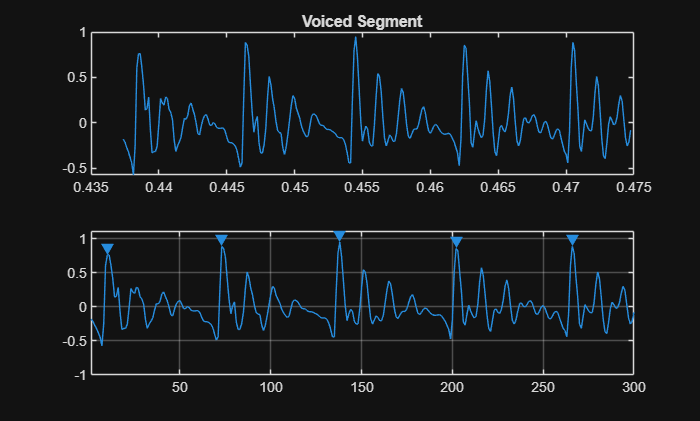

MinPeakHeight = 0.7;      % tune this - the signal indicates that we need minimum 0.7 to get the height of the desired peaks
MinPeakDistance = 60;     % tune this - the signal (from 0 to 300) from the figure has 5 peaks, so we segment it to 300/5 = 60 peak distance

% Plot peaks
findpeaks(voiceSig, 'MinPeakHeight', MinPeakHeight, ...
                     'MinPeakDistance', MinPeakDistance);

% Extract peaks
[peakVals, peakLocs] = findpeaks(voiceSig, ...
    'MinPeakHeight', MinPeakHeight, ...
    'MinPeakDistance', MinPeakDistance);

% Compute pitch period
pitchPeriod = mean(diff(peakLocs)) / fs   % peak period = mean distance between the peak locations / sample frequency

pitchPeriod = 0.0080

### **Part 3:**

Average energy of speech = mean of squared voice signal


$$P = \frac{1}{N}\sum_{n=1}^{N}x^{2}[n]\ \text{.}$$


voiceSigEnergy   = mean(voiceSig.^2)

voiceSigEnergy = 0.0750

unVoiceSigEnergy = mean(unVoiceSig.^2)

unVoiceSigEnergy = 1.5287e-05

### **Part 4:**

Zero crossings are how many times the signal crosses from positive to negative

% voiceSig(1:end-1) Every sample except the last
% voiceSig(2:end  ) Every sample except the first
numZeroCrossVoice   = sum(voiceSig(1:end-1) .* voiceSig(2:end) < 0)       % if < 0 , then voiceSig(n) and voiceSig(n+1) must be positive and negative either arrangement.

numZeroCrossVoice = 51

% unvoiceSig(1:end-1) Every sample except the last
% unvoiceSig(2:end  ) Every sample except the first
numZeroCrossUnVoice = sum(unVoiceSig(1:end-1) .* unVoiceSig(2:end) < 0)   % if < 0 , then unvoiceSig(n) and voiceSig(n+1) must be positive and negative either arrangement.

numZeroCrossUnVoice = 162

The voiced speech pitch period is about 8 ms.

The voiced speech pitch frequency is about 125 Hz.

Talker is likely a Male. 

## Synthesis of Voiced Speech

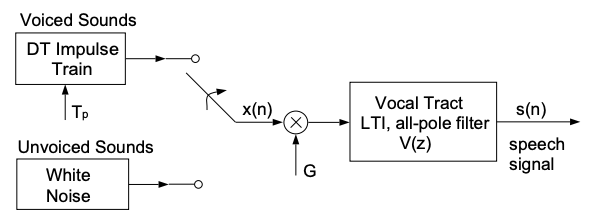

Here, we are loading coeff.mat to get three sets of all-pole filter coefficients: `A1`, `A2`, `A3` (each order 15). This section will consist of three stages.

### STAGE 1: 

ExciteV ( lenN, periodNp ) function returns an N-length impulse train and period Np (e.g. `[1 0 0 ... 0 1 0 0 ...]`)

function sig = ExciteV(lenN, periodNp)
%
% Create a voiced excitation signal
% Input
%     lenN: is the sample length of the signal
%     periodNp: is the pitch period
% Output
%     sig: is the excitation signal

% Set up
% Calc number of reps and the remainder zeros: (Could be useful.)
    sig = zeros(lenN, 1);
    sig(1:periodNp:end) = 1;   % impulse at every periodNp samples
end

### STAGE 2:

Create the excitation signal, with:

- Duration: 40 ms

- Sampling frequency (fs) : 8 kHz

- Pitch period: 8 ms

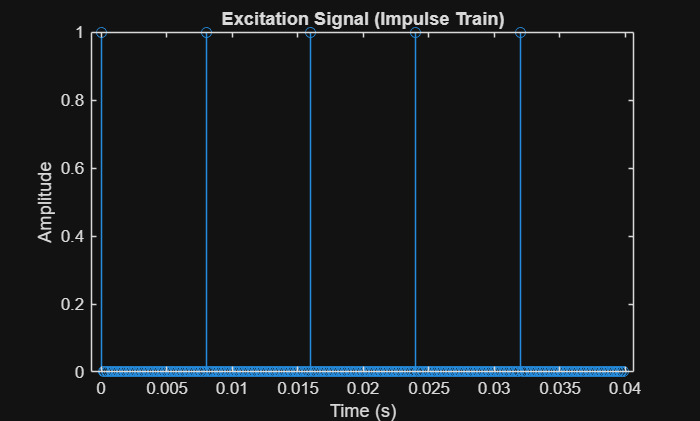

load coeff.mat

dur = 40 * 1e-3;           % Duration
fs = 8000 ;                % Sample frequency

numSamp = dur * fs ;       % number of samples = Duration * Sample Frequency
pitchPeriod = 8 * 1e-3 ;   % Pitch period


numPitchSamp = pitchPeriod * fs ;    % Converts the pitch period from time (seconds) → samples:
tAxis = (0:numSamp-1)*(1/fs) ;       % Creates a time axis in seconds for plotting

% Generate the excitation signal
exciteSignal = ExciteV(double(numSamp),double(numPitchSamp)) ;
figure
stem(tAxis, exciteSignal)
title('Excitation Signal (Impulse Train)')
xlabel('Time (s)')
ylabel('Amplitude')

### STAGE 3:

By calling the function

- Filter the excitation through each of `A1`, `A2`, `A3` using `filter()`

- Plot all three results in one figure using `subplot()`

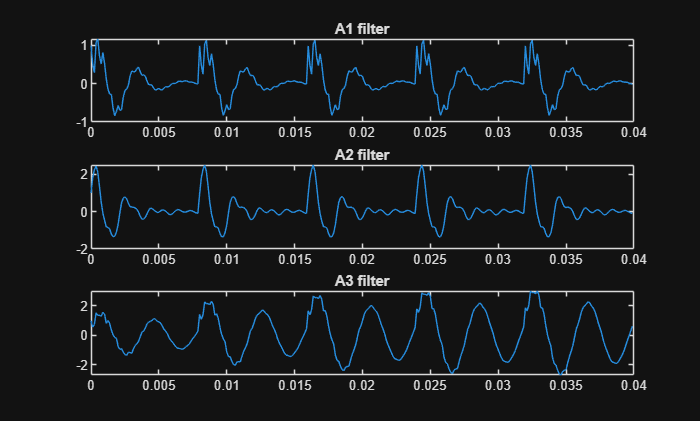

sig1 = filter(1, [1 -A1], exciteSignal ) ;
sig2 = filter(1, [1 -A2], exciteSignal ) ;
sig3 = filter(1, [1 -A3], exciteSignal ) ;


figure
subplot(3,1,1)
plot(tAxis,sig1) ;
title("A1 filter")
subplot(3,1,2)
plot(tAxis, sig2) ;
title("A2 filter")
subplot(3,1,3)
plot(tAxis, sig3) ;
title("A3 filter")

## Frequency Response of Filters

- Write `ExciteV(lenN, periodNp)` — generates an impulse train of length N with period Np

- Create a 40 ms excitation at 8 kHz with 8 ms pitch period

- Filter the excitation through each of `A1`, `A2`, `A3` using `filter()`

- Plot all three results in one figure using `subplot()`

### PART 1

We will now compute the frequency response of each of these filters. The frequency response may be obtained by evaluating V(z) at z = e^(jw). Evaluate this manually and compare with the MATLAB function `freqz()`.  Plot the magnitude of each response versus frequency in Hertz. Use `subplot()` to plot them in the same figure. You should have six plots, three using your own code and three using `freqz()`.

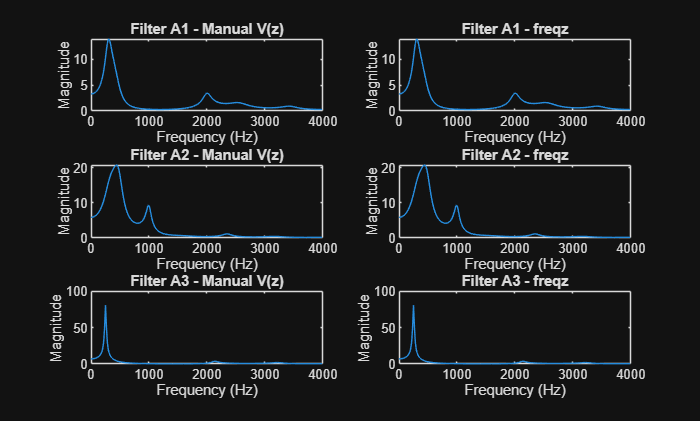

load coeff.mat

Npts = 512 ;    % 512 points
fs = 8000 ;     % 8kHz sample frequency

freq  = (0:Npts/2-1) * (fs/Npts);  % Create frequency axis in Hz (0 to 4000 Hz)
omega = freq / fs * 2 * pi;        % Convert to radians (0 to pi)
zVal  = exp(1j * omega);           % Evaluate on unit circle: z = e^(j*omega)

% Initialise denominator sums for each filter
sumVal1 = zeros(size(zVal)) ;
sumVal2 = zeros(size(zVal)) ; 
sumVal3 = zeros(size(zVal)) ;

% Manually compute denominator of V(z) = 1 / (1 - sum(ak * z^-k))
for I = 1 : length(A1)  
    sumVal1 = sumVal1 + A1(I) * zVal.^(-I);
    sumVal2 = sumVal2 + A2(I) * zVal.^(-I);
    sumVal3 = sumVal3 + A3(I) * zVal.^(-I);
end

% Compute V(z) manually for each filter
Vomega1 = 1 ./ (1 - sumVal1);
Vomega2 = 1 ./ (1 - sumVal2);
Vomega3 = 1 ./ (1 - sumVal3);

% Compute frequency response using MATLAB's freqz for verification
% freqz(B, A) where B=1 (numerator) and A=[1; -coefficients] (denominator)
[H1, ~] = freqz(1, [1; -A1(:)], Npts/2, fs);
[H2, ~] = freqz(1, [1; -A2(:)], Npts/2, fs);
[H3, ~] = freqz(1, [1; -A3(:)], Npts/2, fs);

% Transpose to row vectors to match freq dimensions
H1 = H1.';
H2 = H2.';
H3 = H3.';

% Plot all 6 frequency responses in a 3x2 grid
% Left column = manual V(z), Right column = freqz result
% Peaks in each plot represent formant frequencies of the vocal tract
figure

subplot(3,2,1)
plot(freq, abs(Vomega1))
title('Filter A1 - Manual V(z)')
xlabel('Frequency (Hz)')
ylabel('Magnitude')

subplot(3,2,2)
plot(freq, abs(H1))
title('Filter A1 - freqz')
xlabel('Frequency (Hz)')
ylabel('Magnitude')

subplot(3,2,3)
plot(freq, abs(Vomega2))
title('Filter A2 - Manual V(z)')
xlabel('Frequency (Hz)')
ylabel('Magnitude')

subplot(3,2,4)
plot(freq, abs(H2))
title('Filter A2 - freqz')
xlabel('Frequency (Hz)')
ylabel('Magnitude')

subplot(3,2,5)
plot(freq, abs(Vomega3))
title('Filter A3 - Manual V(z)')
xlabel('Frequency (Hz)')
ylabel('Magnitude')


subplot(3,2,6)
plot(freq, abs(H3))
title('Filter A3 - freqz')
xlabel('Frequency (Hz)')
ylabel('Magnitude')

### PART 2

Use MATLAB's function findpeaks to find the peaks in the spectal response.

formants: Converts the peak locations from sample indices → **actual frequencies in Hz** by indexing into `freq`. Takes only the first 3 peaks

**VOWEL 1**

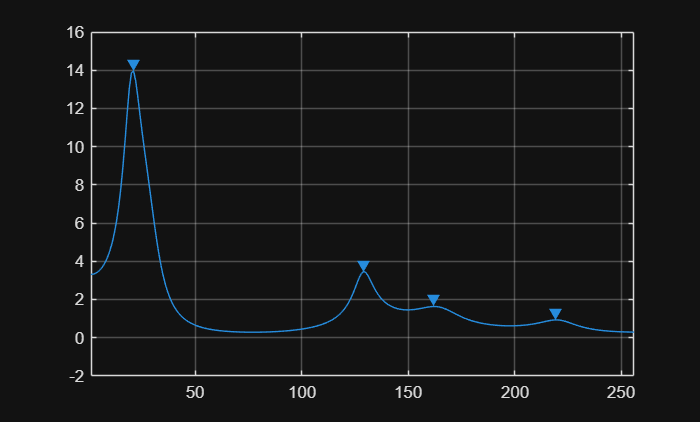

figure
findpeaks(abs(Vomega1), 'MinPeakHeight', 0.5, 'MinPeakDistance', 20);  % 0.5 is the smallest value so that the right-most peak is discovered still

[peakVals1, peakLocs1] = findpeaks(abs(Vomega1), ...
    'MinPeakHeight', 0.5, ...
    'MinPeakDistance', 20);

% peakVals — the magnitude of each detected peak
% peakLocs — the sample index of each peak (not yet in Hz)

formants1 = freq(peakLocs1(1:3))

formants1 = 1.0e+03 *

    0.3125    2.0000    2.5156


**VOWEL 2**

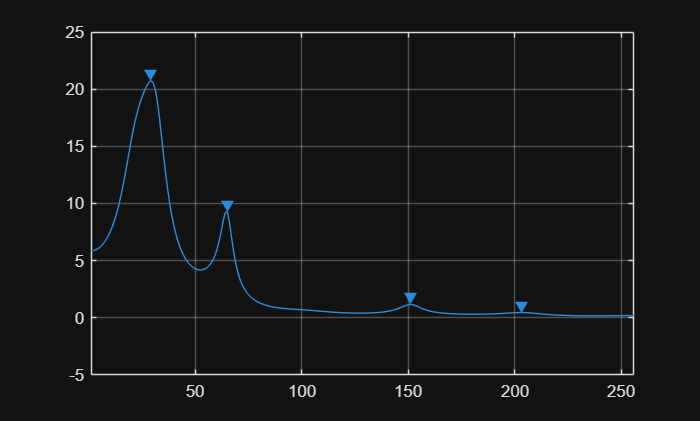

figure
findpeaks(abs(Vomega2), 'MinPeakHeight', 0.2, 'MinPeakDistance', 10);  % 0.2 is the smallest value so that the right-most peak is discovered still

[peakVals2, peakLocs2] = findpeaks(abs(Vomega2), ...
    'MinPeakHeight', 0.2, ...
    'MinPeakDistance', 10);

% peakVals — the magnitude of each detected peak
% peakLocs — the sample index of each peak (not yet in Hz)

formants2 = freq(peakLocs2(1:3))

formants2 = 1.0e+03 *

    0.4375    1.0000    2.3438


**VOWEL 3**

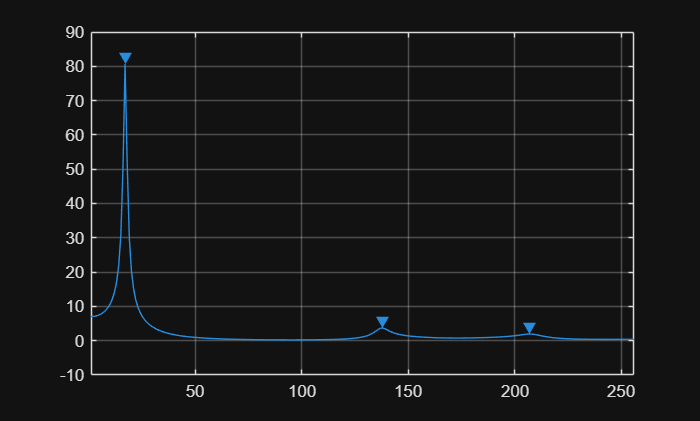

figure
findpeaks(abs(Vomega3), 'MinPeakHeight', 0.5, 'MinPeakDistance', 20);  % 0.5 is the smallest value so that the right-most peak is discovered still

[peakVals3, peakLocs3] = findpeaks(abs(Vomega3), ...
    'MinPeakHeight', 0.5, ...
    'MinPeakDistance', 20);

% peakVals — the magnitude of each detected peak
% peakLocs — the sample index of each peak (not yet in Hz)

formants3 = freq(peakLocs3(1:3))

formants3 = 1.0e+03 *

    0.2500    2.1406    3.2188


## Excitation Signal

**Phonemes**

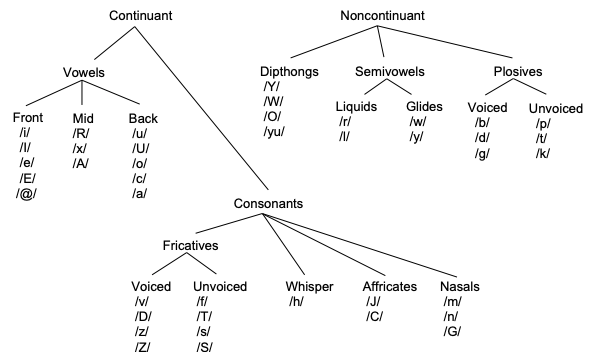

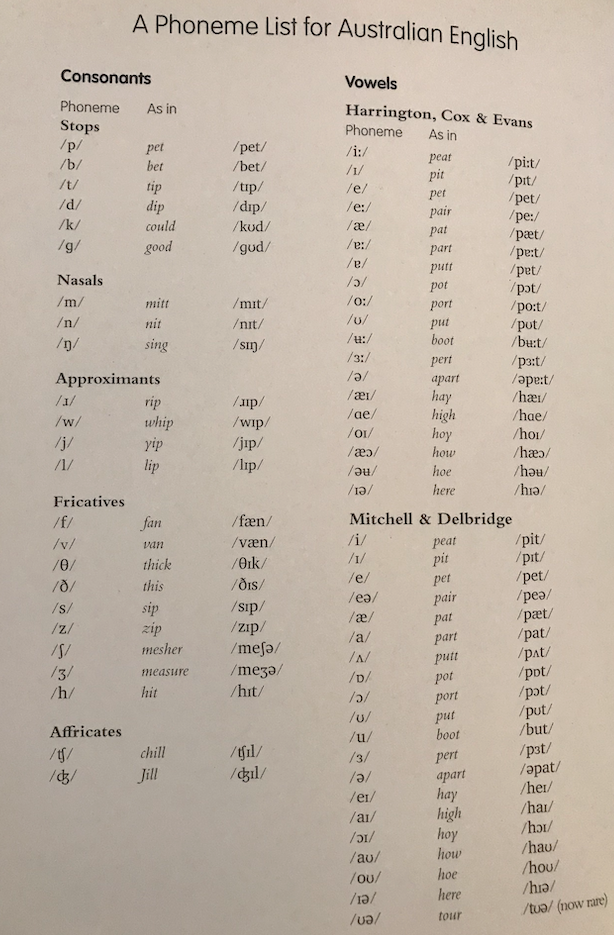

Creating a 1.5 second excitation signal and listen to the simulated vowel sound. Assume a sampling frequency of 8 kHz (0.125 ms/sample) and a pitch period of 8 ms.

Try to determine the identity of each vowel. To listen to the resulting signal, you will need to copy your code into the Lab3Image.mlx livescript (and the ExciteV function) and uncomment the `playObj` code.

Assume that you have the correct ExciteV function available to you.

load coeff.mat

dur          = 1.5;                           % 1.5 seconds
fs           = 8000;                          % 8 kHz sampling frequency
pitchPeriod  = 0.008;                         % 8 ms pitch period
numSamp      = dur * fs;                      % total number of samples
numPitchSamp = pitchPeriod * fs;              % pitch period in samples

% Generates the impulse train: series of 1s separated by 0s, repeating every 64 samples. This mimics the periodic bursts of air from the vocal cords.
exciteSignal = ExciteV(numSamp, numPitchSamp); % voiced excitation impulse train

% Filter with each set of coefficients and normalise
sig1 = filter(1, [1; -A1(:)], exciteSignal);
sig1 = sig1 / max(abs(sig1));                 % normalise

sig2 = filter(1, [1; -A2(:)], exciteSignal);
sig2 = sig2 / max(abs(sig2));                 % normalise

sig3 = filter(1, [1; -A3(:)], exciteSignal);
sig3 = sig3 / max(abs(sig3));                 % normalise

% Play the sounds
playObj = audioplayer(sig1,fs) ;
playblocking(playObj) ;
playObj = audioplayer(sig2,fs) ;
playblocking(playObj) ;
playObj = audioplayer(sig3,fs) ;
playblocking(playObj) ;